# Assignment 2

**Kapil Shindekar Roll No. 250504**

### Question 1

a]

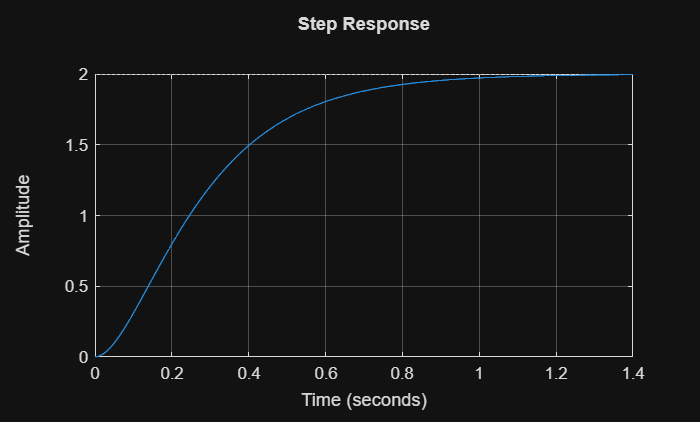

num=100;
den=[1 15 50];
G=tf(num,den);
step(G),grid on;

Theoretical Calculations

Time Constant = 1/5 (as s= -5 is a pole)

Rise time = $2\ldotp 2\tau$ =  0.44 sec

Settling time = 4$\tau$ =0.8 sec

Peak Oveshoot =0

Steady State error = 1-2= -1

stepinfo(G)

ans = struct with fields:
         RiseTime: 0.5180
    TransientTime: 0.9200
     SettlingTime: 0.9200
      SettlingMin: 1.8045
      SettlingMax: 1.9983
        Overshoot: 0
       Undershoot: 0
             Peak: 1.9983
         PeakTime: 1.5565


**b] **

% Defining the P controller
C_p=pid(0.5)


C_p =
 
  Kp = 0.5
 
P-only controller.


T = feedback(C_p*G,1)


T =
 
         50
  ----------------
  s^2 + 15 s + 100
 
Continuous-time transfer function.


% Simulate the step response of the closed-loop system
step(T), grid on,hold on;
%Performance metrics
stepinfo(T)

ans = struct with fields:
         RiseTime: 0.2288
    TransientTime: 0.5743
     SettlingTime: 0.5743
      SettlingMin: 0.4524
      SettlingMax: 0.5142
        Overshoot: 2.8369
       Undershoot: 0
             Peak: 0.5142
         PeakTime: 0.4728


final_value=dcgain(T);
sserror=1- final_value

sserror = 0.5000

As the system has no integrators and the proportional controller adds only gain and does not change the system type the steady state error exists.  

**c]**

C_i=pid(0.5,1.5)


C_i =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.5, Ki = 1.5
 
Continuous-time PI controller in parallel form.


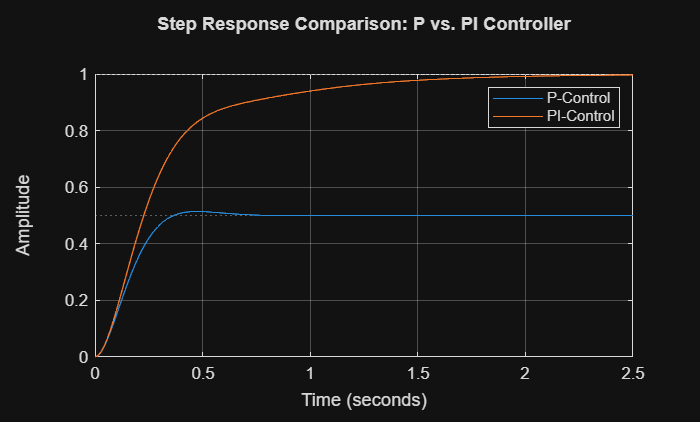

T_new = feedback(C_i*G, 1);
step(T_new), title('Step Response Comparison: P vs. PI Controller');
legend('P-Control', 'PI-Control');grid on;hold off;

%Performance metrics
stepinfo(T_new)

ans = struct with fields:
         RiseTime: 0.6278
    TransientTime: 1.5377
     SettlingTime: 1.5377
      SettlingMin: 0.9016
      SettlingMax: 0.9981
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9981
         PeakTime: 2.6861


final_value_new = dcgain(T_new);
sserror_new = 1 - final_value_new

sserror_new = 0

The steady state error was eliminated because the integral term introduced an integrator in the system. Thus when the value of s is zero the transfer function goes to infinity and the error term goes to zero.

**d]**

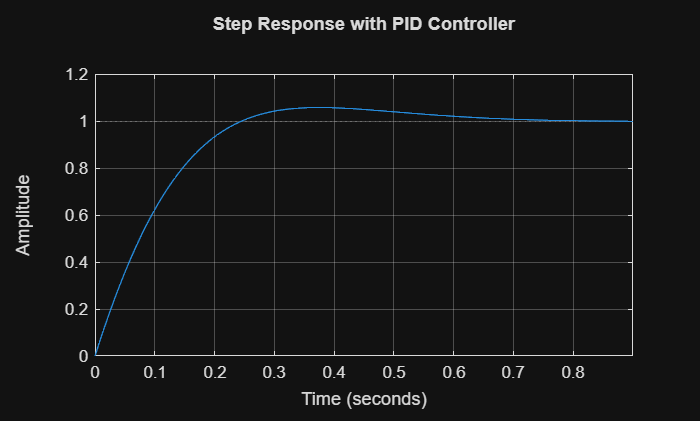

Kp_tuned=1.5;Ki_tuned=7;Kd_tuned=0.08;
C_pid=pid(Kp_tuned,Ki_tuned,Kd_tuned);
T_pid = feedback(C_pid*G, 1);
step(T_pid), title('Step Response with PID Controller');grid on;

stepinfo(T_pid)

ans = struct with fields:
         RiseTime: 0.1712
    TransientTime: 0.6008
     SettlingTime: 0.6008
      SettlingMin: 0.9003
      SettlingMax: 1.0573
        Overshoot: 5.7271
       Undershoot: 0
             Peak: 1.0573
         PeakTime: 0.3755


% Performance metrics
final_value_pid = dcgain(T_pid);
sserror_pid = 1 - final_value_pid

sserror_pid = 0

### Question 2

**a]**

t=0:0.1:20

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


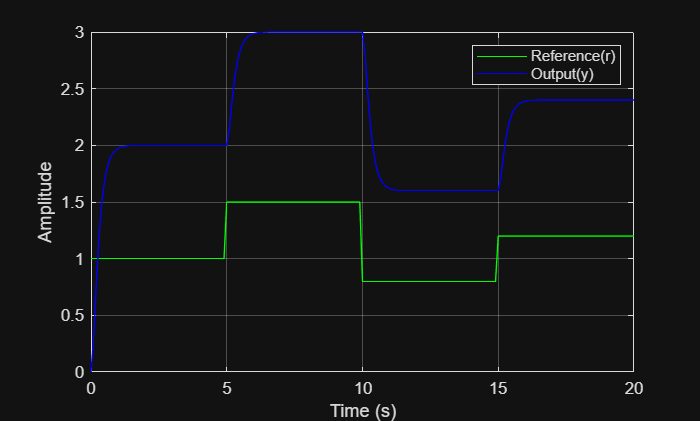

r = zeros (size (t));

G=tf(100,[1 15 50]);
for i = 1: length (t)
    if t(i) < 5
    r(i) = 1;
    elseif t(i) < 10
    r(i) = 1.5;
    elseif t(i) < 15
    r(i) = 0.8;
    else
    r(i) = 1.2;
    end
end
[y,t_out]=lsim(G,r,t);
plot (t, r, 'g', t_out , y, 'b');grid on;
xlabel('Time (s)');
ylabel('Amplitude');
legend ('Reference(r)', 'Output(y) ');

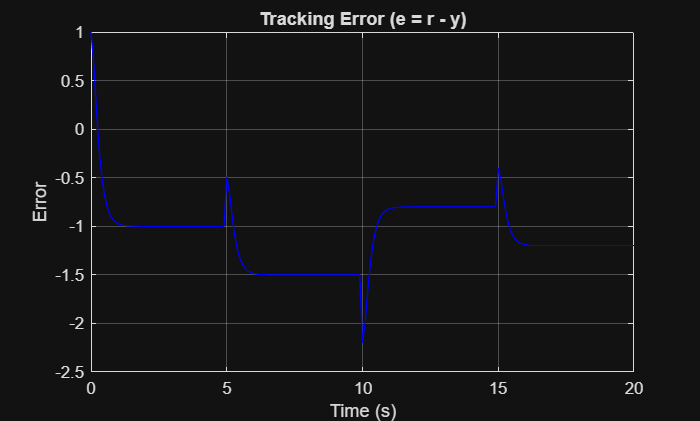

error_signal = r' - y;
plot(t, error_signal, 'b');
title('Tracking Error (e = r - y)');
xlabel('Time (s)');
ylabel('Error');
grid on;

**b]**

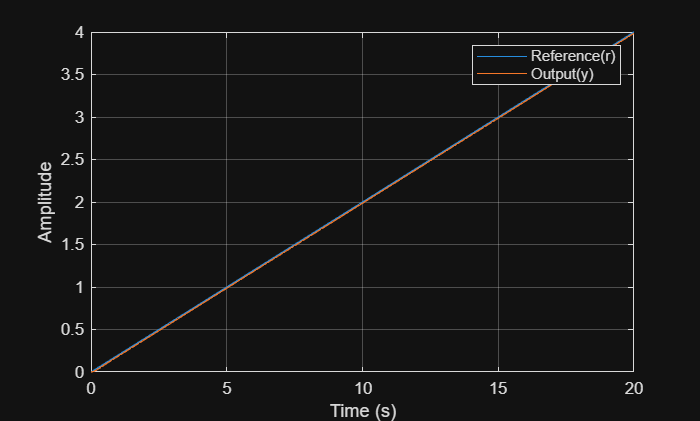

u = 0.2 * t;
Kp_tuned=1.5;Ki_tuned=7;Kd_tuned=0.08;
C_pid=pid(Kp_tuned,Ki_tuned,Kd_tuned);
T_pid = feedback(C_pid*G, 1);
[y_ramp, t_out] = lsim (T_pid, u, t);
% Analyze the tracking performance of the PID controller
e_ramp = u' - y_ramp;
figure ;
plot (t, u);
hold on;
plot (t, y_ramp);
xlabel('Time (s)');
ylabel('Amplitude');
hold off;grid on;legend ('Reference(r)', 'Output(y) ');

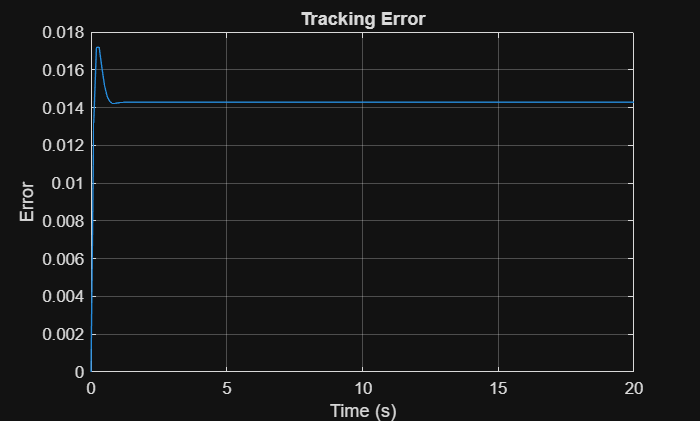

plot(t, e_ramp);
title('Tracking Error');
xlabel('Time (s)');
ylabel('Error');
grid on;

final_error_ramp = mean(e_ramp(end-100:end));
fprintf('Final Steady-State Error: %.4f\n', final_error_ramp);

Final Steady-State Error: 0.0143


To track a ramp the which is increasing linearly the control signal must also be increase linearly, the integral term can only produce a linearly increasing output if the input error term is non zero.

**c]**

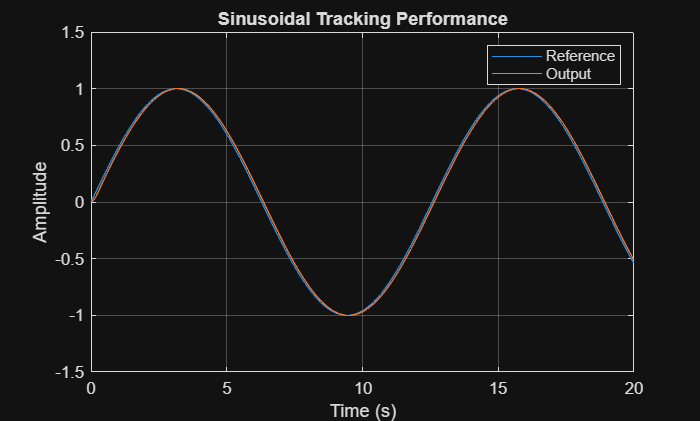

r_sin = sin(0.5 * t);
[y_sin, t_out] = lsim(T_pid, r_sin, t);
figure;
plot(t, r_sin); hold on;
plot(t, y_sin);
title('Sinusoidal Tracking Performance');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Reference', 'Output');hold off;
grid on;

Time lag from observation is zero.

### Question 3

**a] **

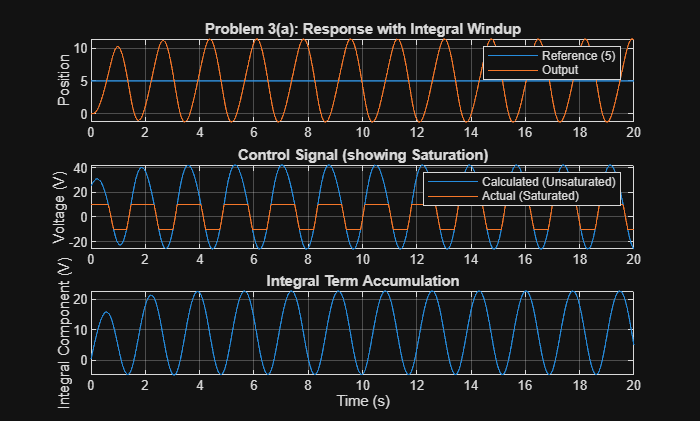

%% Problem 3(a): Observing Integral Windup (Without Anti-Windup)

% 1. Define Plant Model
% G(s) = 50 / (s^3 + 8s^2 + 25s + 20) 
num_p3 = [50];
den_p3 = [1 8 25 20];
sys_continuous = tf(num_p3, den_p3);

% Discretize Plant for Simulation
% We need a discrete model (A, B, C, D) to simulate inside a for-loop
dt = 0.01; % Time step
sys_discrete = c2d(ss(sys_continuous), dt, 'zoh');
[A, B, C, D] = ssdata(sys_discrete);

% 2. Controller Parameters & Setup
Kp = 5;
Ki = 8;
u_lim = 10; % Actuator limit (+/- 10 Volts) 

% Time Vector
T_final = 20;
t = 0:dt:T_final;
N = length(t);

% Pre-allocate arrays for speed and storage
y = zeros(1, N);        % System Output
u_raw = zeros(1, N);    % Calculated Control (Unsaturated)
u_sat = zeros(1, N);    % Actual Control (Saturated)
e_int_arr = zeros(1, N);% Integral Term History
error_arr = zeros(1, N);% Error History

% Initial Conditions
x = [0; 0; 0];          % Initial state of the plant (3 states for 3rd order)
e_int = 0;              % Initial integral value

% Reference Signal (Step input of magnitude 5) 
r = 5 * ones(size(t));

% 3. Simulation Loop
for k = 1:N
    % --- Sensor Measurement ---
    % Get current output from plant state
    current_y = C * x;
    y(k) = current_y;
    
    % --- Controller Calculation ---
    % Calculate Error
    error = r(k) - current_y;
    error_arr(k) = error;
    
    % Integral Update (Standard - CAUSES WINDUP)
    % We continue integrating error even if actuator is saturated 
    e_int = e_int + error * dt;
    
    % PID Control Law (PI only for this part)
    u_p = Kp * error;
    u_i = Ki * e_int;
    u_total = u_p + u_i;
    
    % --- Actuator Saturation ---
    % Apply limits: max(min(u, 10), -10) 
    if u_total > u_lim
        u_actual = u_lim;
    elseif u_total < -u_lim
        u_actual = -u_lim;
    else
        u_actual = u_total;
    end
    
    % Store values
    u_raw(k) = u_total;
    u_sat(k) = u_actual;
    e_int_arr(k) = u_i; % Plotting the Integral Term (Ki * e_int)
    
    % --- Plant Update ---
    % Update state for next time step: x[k+1] = Ax[k] + Bu[k]
    x = A * x + B * u_actual;
end

% 4. Plotting Results
figure;

% Plot 1: Reference vs Output
subplot(3,1,1);
plot(t, r); hold on;
plot(t, y);
title('Problem 3(a): Response with Integral Windup');
ylabel('Position');
legend('Reference (5)', 'Output');
grid on;

% Plot 2: Control Effort (Saturated vs Unsaturated)
subplot(3,1,2);
plot(t, u_raw); hold on;
plot(t, u_sat);
title('Control Signal (showing Saturation)');
ylabel('Voltage (V)');
legend('Calculated (Unsaturated)', 'Actual (Saturated)');
grid on;

% Plot 3: Integral Term
subplot(3,1,3);
plot(t, e_int_arr);
title('Integral Term Accumulation');
xlabel('Time (s)');
ylabel('Integral Component (V)');
grid on;

i] Saturation occurs immediately at t=0. The error is 5, so the proportional term alone is K_p *5 = 25. Since the motor limit is 10V, the controller instantly goes to the Max limit and stays there.

ii] The integral term **keeps increasing linearly**. Even though the motor is already working at max capacity (10V), the integrator doesn't know this. It continues to sum up the error, calculating a theoretical control signal that reaches huge values (likely 40V or more), which is physically impossible.

iii] Eventually, the output (y) reaches the target (5). However, the integrator has wound up to a massive value.This causes massive overshoot and a very long settling time compared to a linear system.

**b]**

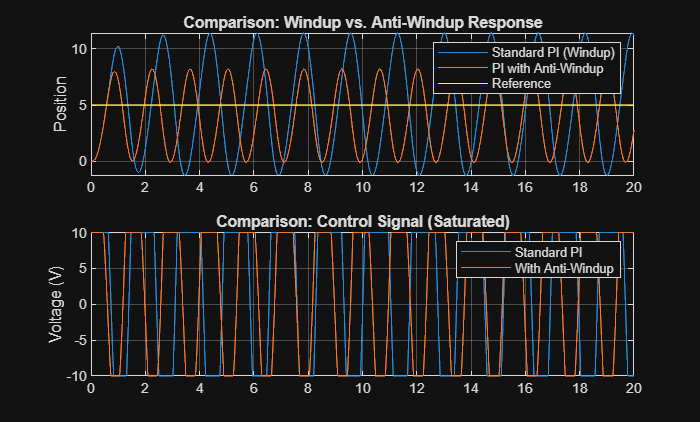

% 1. Define Anti-Windup Parameters
Kt = sqrt(Ki); % Tracking gain [cite: 95]

% 2. Simulation Setup (Same as Part a)
% Re-initialize variables for the Anti-Windup (AW) case
y_aw = zeros(1, N);
u_raw_aw = zeros(1, N);
u_sat_aw = zeros(1, N);
e_int_aw = zeros(1, N);
x_aw = [0; 0; 0];  % Initial state
e_int_val = 0;     % Integral accumulator

% 3. Simulation Loop with Anti-Windup
for k = 1:N
    % Measurement
    current_y = C * x_aw;
    y_aw(k) = current_y;
    
    % Error Calculation
    error = r(k) - current_y;
    
    % --- PID Calculation (Step 1: Calculate "Proposed" Control) ---
    % Note: We calculate u_total based on the CURRENT integral value first
    u_p = Kp * error;
    u_i = Ki * e_int_val;
    u_total = u_p + u_i;
    
    % --- Saturation Check ---
    if u_total > u_lim
        u_actual = u_lim;
    elseif u_total < -u_lim
        u_actual = -u_lim;
    else
        u_actual = u_total;
    end
    
    % --- Integral Update (Step 2: Back-Calculation) ---
    % Modify the accumulation based on the difference (u_actual - u_total)
    % Formula: d(Integral)/dt = error + (u_sat - u)/Kt
    back_calc_term = (u_actual - u_total) / Kt;
    e_int_val = e_int_val + (error + back_calc_term) * dt; % [cite: 173]
    
    % Store values
    u_raw_aw(k) = u_total;
    u_sat_aw(k) = u_actual;
    e_int_aw(k) = u_i;
    
    % Update Plant
    x_aw = A * x_aw + B * u_actual;
end

% 4. Plot Comparison: Windup (Part a) vs Anti-Windup (Part b)
figure;

% Comparison 1: Output Response
subplot(2,1,1);
plot(t, y); hold on;      % From Part (a)
plot(t, y_aw);             % From Part (b)
plot(t, r);
title('Comparison: Windup vs. Anti-Windup Response');
legend('Standard PI (Windup)', 'PI with Anti-Windup', 'Reference');
ylabel('Position');
grid on;

% Comparison 2: Control Effort
subplot(2,1,2);
plot(t, u_sat); hold on;    % From Part (a)
plot(t, u_sat_aw);         % From Part (b)
title('Comparison: Control Signal (Saturated)');
legend('Standard PI', 'With Anti-Windup');
ylabel('Voltage (V)');
grid on;


% 5. Quantitative Performance Table [cite: 99]
% Function to calculate settling time (2% criterion)
get_settling = @(y_sig) t(find(abs(y_sig - 5) > 0.02*5, 1, 'last'));
% Function to calculate time in saturation (u = 10 or -10)
get_sat_time = @(u_sig) sum(abs(u_sig) >= (u_lim - 0.01)) * dt;

% Metrics for Standard PI (Part a)
os_a = (max(y) - 5)/5 * 100;
ts_a = get_settling(y);
tsat_a = get_sat_time(u_sat);

% Metrics for Anti-Windup PI (Part b)
os_b = (max(y_aw) - 5)/5 * 100;
ts_b = get_settling(y_aw);
tsat_b = get_sat_time(u_sat_aw);

Peformance Analysis

**c]**

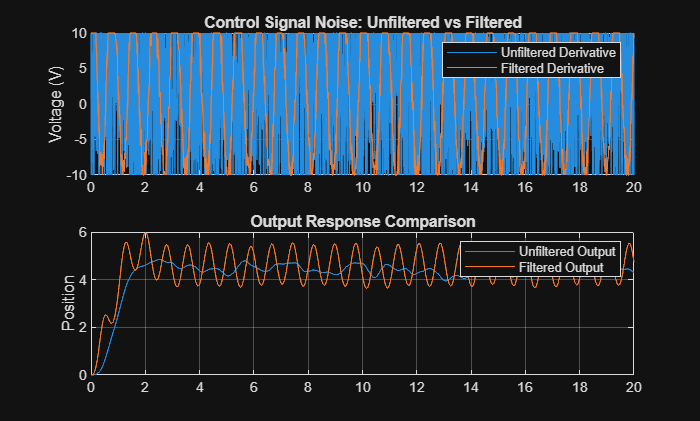

%% Problem 3(c): Derivative Noise and Low-Pass Filtering

% 1. Setup Parameters
Kp = 5; Ki = 8; Kd = 2; % 
Kt = sqrt(Ki);          % Anti-windup tracking gain
tau = 0.1;              % Filter time constant 
alpha = tau / (tau + dt); % Filter coefficient 

% Simulation arrays
% Case 1: Unfiltered PID
y_unfil = zeros(1, N);
u_unfil = zeros(1, N);
x_unfil = [0; 0; 0];
e_int_unfil = 0;
e_prev_unfil = 0;

% Case 2: Filtered PID
y_fil = zeros(1, N);
u_fil = zeros(1, N);
x_fil = [0; 0; 0];
e_int_fil = 0;
e_fil_prev = 0;      
e_fil_val = 0;       

% Set random seed for reproducibility
rng(42); 
noise_vector = 0.05 * randn(1, N); % Pre-generate noise 

% Simulation 1: PID with Unfiltered Derivative

for k = 1:N
    % Measurement with Noise
    y_pure = C * x_unfil;
    y_noisy = y_pure + noise_vector(k);
    y_unfil(k) = y_pure; % Store true position
    
    % Error
    error = r(k) - y_noisy;
    
    % Derivative (Raw Finite Difference) 
    u_d = Kd * (error - e_prev_unfil) / dt;
    
    % Proportional & Integral
    u_p = Kp * error;
    u_i = Ki * e_int_unfil;
    
    % PID Total
    u_total = u_p + u_i + u_d;
    
    % Saturation
    u_actual = max(min(u_total, u_lim), -u_lim);
    
    % Anti-Windup Update
    back_calc = (u_actual - u_total) / Kt;
    e_int_unfil = e_int_unfil + (error + back_calc) * dt;
    
    % Update State
    x_unfil = A * x_unfil + B * u_actual;
    e_prev_unfil = error;
    
    % Store Control Signal
    u_unfil(k) = u_actual;
end


% Simulation 2: PID with Filtered Derivative

for k = 1:N
    % Measurement with Noise
    y_pure = C * x_fil;
    y_noisy = y_pure + noise_vector(k);
    y_fil(k) = y_pure;
    
    % Error
    error = r(k) - y_noisy;
    
    % Filter the Error First 
    % e_filtered(k) = alpha * e_filtered(k-1) + (1-alpha) * e(k)
    e_fil_val = alpha * e_fil_prev + (1 - alpha) * error;
    
    % Derivative (Using Filtered Error) 
    u_d = Kd * (e_fil_val - e_fil_prev) / dt;
    
    % PID Total
    u_p = Kp * error;
    u_i = Ki * e_int_fil;
    u_total = u_p + u_i + u_d;
    
    % Saturation & Anti-Windup
    u_actual = max(min(u_total, u_lim), -u_lim);
    back_calc = (u_actual - u_total) / Kt;
    e_int_fil = e_int_fil + (error + back_calc) * dt;
    
    % Update State
    x_fil = A * x_fil + B * u_actual;
    
    % Update Previous Values
    e_fil_prev = e_fil_val;
    e_int_fil = e_int_fil + (error + back_calc) * dt; % Oops, correction below
    
    % Store
    u_fil(k) = u_actual;
end


% 3. Plotting and Analysis

figure;


subplot(2,1,1);
plot(t, u_unfil); hold on;
plot(t, u_fil);
title('Control Signal Noise: Unfiltered vs Filtered');
ylabel('Voltage (V)');
legend('Unfiltered Derivative', 'Filtered Derivative');
grid on;


subplot(2,1,2);
plot(t, y_unfil); hold on;
plot(t, y_fil);
title('Output Response Comparison');
legend('Unfiltered Output', 'Filtered Output');
ylabel('Position');
grid on;


% 4. Calculate Standard Deviation of Control Signal 
std_unfil = std(u_unfil);
std_fil = std(u_fil);

Derivative Noise Analysis

`Std Dev of Control (Unfiltered): 7.9783 V`

`Std Dev of Control (Filtered):   7.6991 V`

`Noise Reduction Factor:          1.04x`

Filtering reduces noise amplification because the Low-Pass Filter lowers the amplitude of frequencies above its cutoff (approx $\frac{1}{\tau }$). Since measurement noise is high-frequency, it is blocked, preventing the derivative term from reacting violently to it.

**d]**

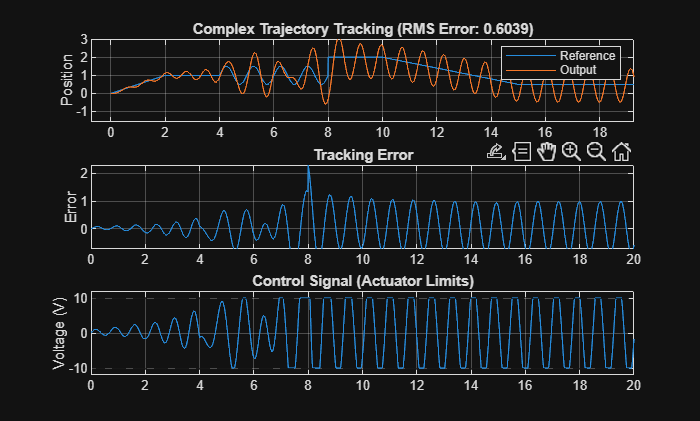

% Controller Parameters
Kp = 5; Ki = 8; Kd = 2;
Kt = sqrt(Ki);             % Anti-windup gain
u_lim = 10;                % Saturation limit
tau = 0.1;                 % Filter time constant
alpha = tau / (tau + dt);  % Filter coefficient

for k = 1:N
    ti = t(k);
    if ti < 2
        r(k) = 0.5 * ti;                   % Ramp Up
    elseif ti < 4
        r(k) = 1;                          % Hold
    elseif ti < 8
        r(k) = 1 + 0.5 * sin(2*pi*(ti-4)); % Oscillation
    elseif ti < 10
        r(k) = 2;                          % Step Up
    elseif ti < 15
        r(k) = 2 - 0.3 * (ti - 10);        % Ramp Down
    else
        r(k) = 0.5;                        % Final Hold
    end
end

% 3. Simulation Initialization
y = zeros(1, N);
u = zeros(1, N);
e_arr = zeros(1, N);

x = [0; 0; 0];      % Plant State
e_int = 0;          % Integral Accumulator
e_fil_prev = 0;     % Filter State

% 4. Simulation Loop (Combined Features)
for k = 1:N
    % Measure
    current_y = C * x;
    y(k) = current_y;
    
    % Error
    error = r(k) - current_y;
    e_arr(k) = error;
    
    % Filtered Derivative
    % Filter the error: e_fil = alpha*prev + (1-alpha)*curr
    e_fil = alpha * e_fil_prev + (1 - alpha) * error;
    % Derivative on filtered error
    u_d = Kd * (e_fil - e_fil_prev) / dt;
    
    % --- Proportional & Integral ---
    u_p = Kp * error;
    u_i = Ki * e_int;
    
    % --- Total Control & Saturation ---
    u_total = u_p + u_i + u_d;
    
    % Apply Limits
    if u_total > u_lim
        u_sat = u_lim;
    elseif u_total < -u_lim
        u_sat = -u_lim;
    else
        u_sat = u_total;
    end
    
    u(k) = u_sat;
    
    % --- Anti-Windup Update ---
    % Back-calculation
    back_calc = (u_sat - u_total) / Kt;
    e_int = e_int + (error + back_calc) * dt;
    
    % --- Updates ---
    x = A * x + B * u_sat;
    e_fil_prev = e_fil;
end

% 5. Performance Metrics
% RMS Error Calculation 
rms_error = sqrt(mean(e_arr.^2));

% 6. Plotting
figure;

% Plot 1: Tracking Performance
subplot(3,1,1);
plot(t, r); hold on;
plot(t, y);hold off;
title(['Complex Trajectory Tracking (RMS Error: ', num2str(rms_error, '%.4f'), ')']);
legend('Reference', 'Output');
ylabel('Position');
grid on;

% Plot 2: Tracking Error
subplot(3,1,2);
plot(t, e_arr);
title('Tracking Error');
ylabel('Error');
grid on;

% Plot 3: Control Effort & Limits
subplot(3,1,3);
plot(t, u); hold on;
yline(10, 'k--');  % Show Upper Limit
yline(-10, 'k--'); % Show Lower Limit
title('Control Signal (Actuator Limits)');
ylabel('Voltage (V)');
ylim([-12 12]);
grid on;

`Final Performanc`

`RMS Tracking Error: 0.6039`

**Ramp Segments (0-2s, 10-15s):**  A small, constant non-zero error during these segments. This confirms the system is Type 1 . The controller must maintain a small error to generate the increasing control signal required to push the motor faster and faster.

**Step Change (8s):** At t=8s, the reference jumps to 2. The control signal (Plot 3) likely hits the +10V limit instantly. Due to the **Anti-Windup** logic, once the output gets close to 2, the control signal pulls back from the limit immediately, preventing excessive overshoot.

**Sinusoid (4-8s):** The tracking should be quite tight. The **Derivative term (****K_d****)** helps here by predicting the wave's movement, minimizing phase lag.

**Actuator Limits:** The 3rd plot clearly shows the control signal "clipping" at +10V and -10V during aggressive changes, proving that the constraints were respected throughout the simulation.